%load('runme_data','M','B')

d65 = B;

spd_target_orig = d65;

spd_0 = ls.spd_0';
spd_max = ls.spd_all' - spd_0;

sc = 0.05

sc = 0.0500

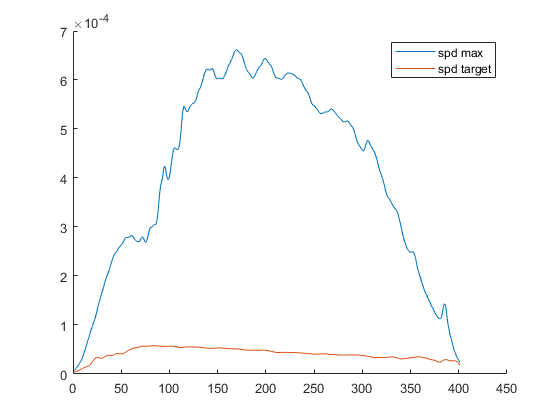


clf
hold on
plot(spd_max)
plot(spd_target_orig*sc)
legend('spd max','spd target')

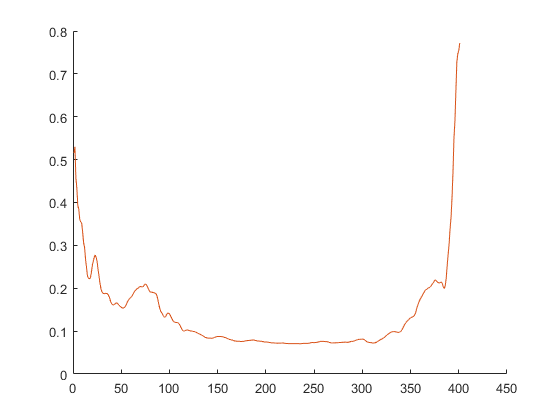


spd_target = spd_target_orig .* sc;
ref_target_orig = (spd_target - spd_0) ./ spd_max;
ref_target = min(1,ref_target_orig);

clf
hold on
plot(ref_target_orig)
plot(ref_target)

ref_m = ls.reflectance';

vec_a_orig = R_callRsolver1024(ref_m,ref_target);

ans = 'Solving M * A = B with R...'

ans = 0

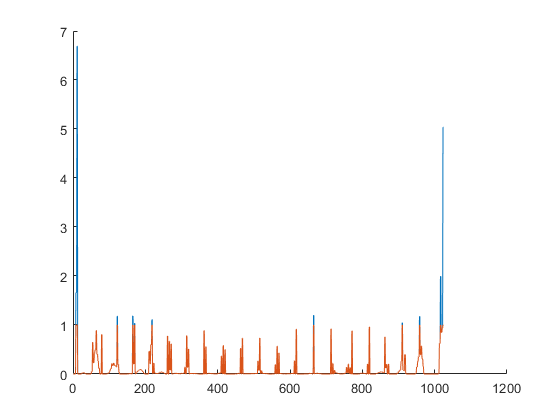


vec_a = min(1,vec_a_orig);

clf
hold on
plot(vec_a_orig)
plot(vec_a)

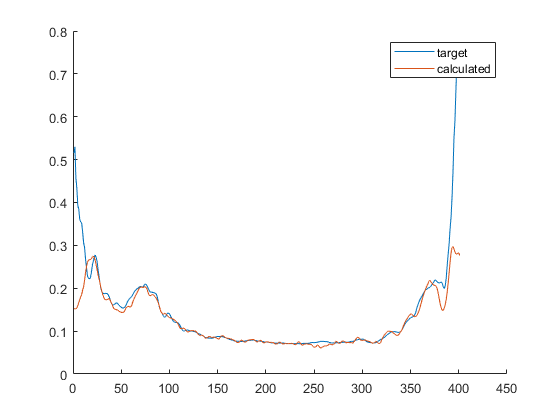

clf
hold on
plot(ref_target)
ref = ref_m * vec_a;
plot(ref)
legend('target','calculated')

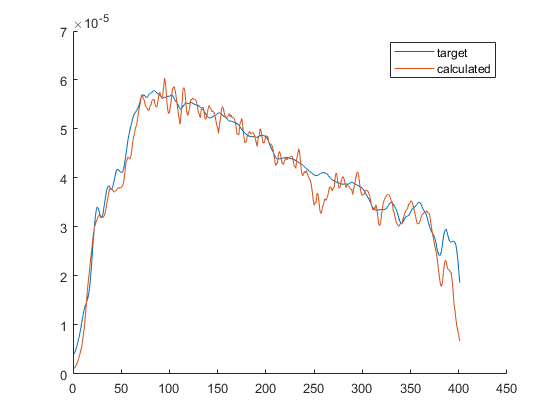

clf
hold on
plot(spd_target)
spd = spd_max .* ref + spd_0;
plot(spd)
legend('target','calculated')

ol.setColumn1024(vec_a)
mea = cs.measure;

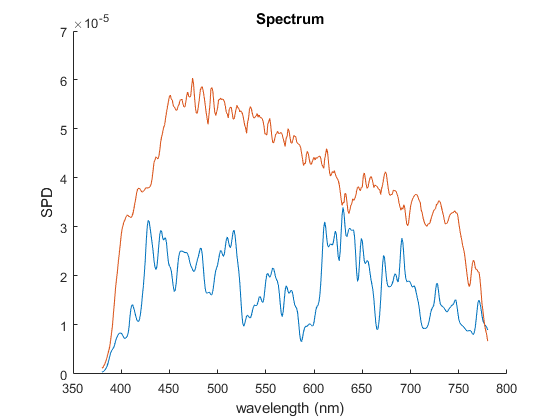


clf
hold on
mea.plot
plot(380:780,spd)

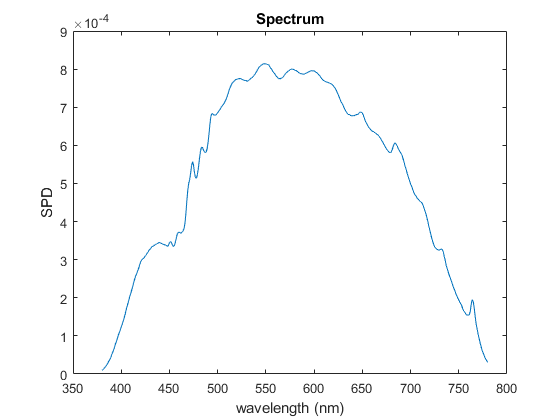

ol.setColumn1024(LightSim.multiple_peaks(1:1024))
mea_all = cs.measure;
clf
mea_all.plot

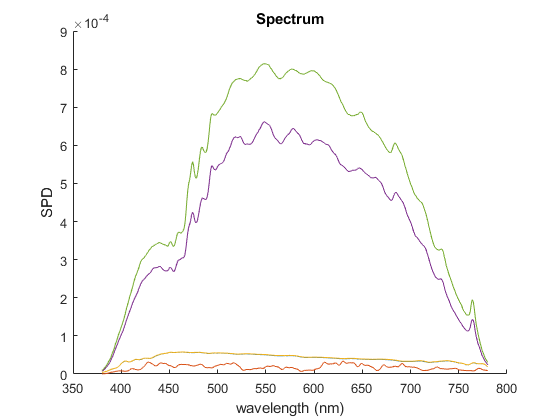

clf
hold on
plot(380:780,spd_max .* ref_target)
mea.plot
plot(380:780,spd_target)
plot(380:780,spd_max)
mea_all.plot

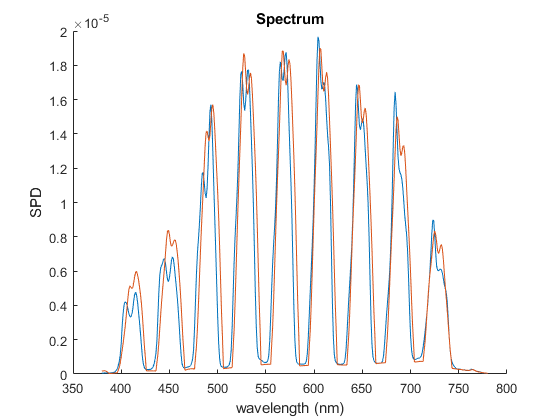

c_range = [1:100:1000];

ol.setColumn1024(LightSim.multiple_peaks(c_range))
mea_500 = cs.measure;

ol.setColumn1024(LightSim.multiple_peaks([1:1024]))
mea_all = cs.measure;

s_pred = ls.predict_by_filter(LightSim.multiple_peaks(c_range));

clf
hold on
t_500 = mea_500.amplitude ./ mea_all.amplitude;
%plot(t_500)
mea_500.plot
plot(380:780,s_pred)